# Tuning ottimale controllori PID

## Schema di controllo

### Decentralizzato

Un controllore indipendente per ogni giunto. Le mutue influenze tra giunti sono viste come disturbi causati da un sistema sull'altro da compensare nel controllore dell'altro

## Struttura di controllo (per il singolo giunto)

### Doppio loop posizione-velocità (cascata) + SP weight

Ogni giunto è controllato da un controllore che riceve in input PV.POS e PV.VEL misurate e il set-point SP.POS. All'interno del controllore, alloggia il doppio loop, costituito, ad esempio, da:

- un *PD* per il **loop interno** (input: PV.VEL e MV del controllore esterno - output: coppia fornita al sistema)

- un *PID* per il **loop esterno** (input: PV.POS e SP.POS filtrato - output: velocità fornita in input al controllore interno)

- un *LPF* per implementare il **SP weight** (input: SP.POS - output SP.POS filtrato) 

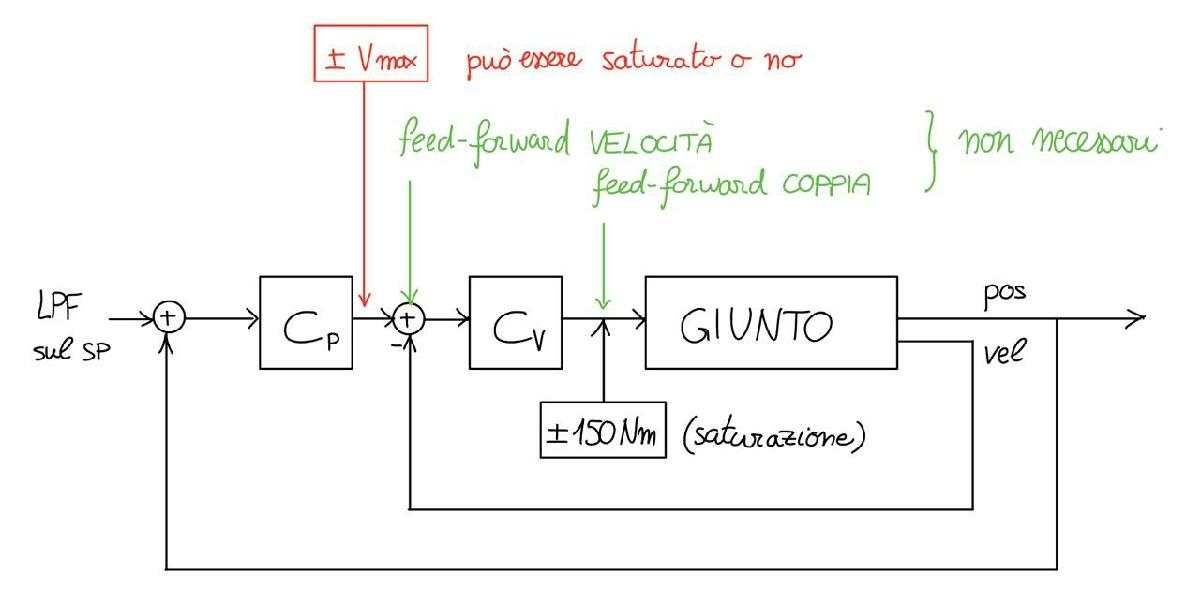

Note:

- implementare le **saturazioni** di coppia e velocità massima nei controllori opportuni

- implementare **anti-windup** per i controllori contenenti azione integrale

- valutare se possono servire i **feed-forward**

- loop interno veloce per la reiezione dei disturbi sul carico (influenze dell'altro giunto), loop esterno più lento ma sufficientemente veloce da seguire il SP in modo efficiente

- **taratura** di ogni sottocontrollore (`Cp_joint1`, `Cv_joint1`, `Cp_joint2`, `Cv_joint2`) in modo **ottimale** con `GlobalSearch`, includendo i **vincoli di robustezza e reiezione disturbi**

## Taratura ottima con vincoli robusti

Determinare $C(s)$ in modo che soddisfi vincoli in frequenza e ottimizzi una cifra di merito.

- PID con filtro sull'azione derivativa e filtro complessivo:    $C(s)=PID_{filt}(s)=\left(K_p+\frac{K_i}{s}+\frac{K_d\cdot s}{T_{fd}s+1}\right) \cdot \frac{1}{T_{fu}s+1}$

- PID con filtro sull'azione derivativa:    $C(s)=PID(s)=K_p+\frac{K_i}{s}+\frac{K_d\cdot s}{T_fs+1}$

- PD con filtro sull'azione derivativa:     $C(s)=PD(s)=K_p+\frac{K_d\cdot s}{T_fs+1}$

- PI:     $C(s)=PI(s)=K_p+\frac{K_i}{s}$

Eseguiamo il tuning nel dominio continuo (tariamo un controllore continuo sfruttando il modello continuo del processo) e in seguito discretizziamo il controllore ottenuto.

## Caricamento modelli dei processi

clear; close all; clc;
s = tf('s'); % variabile s per il dominio delle frequenze

Aggiungo opzione per evitare la molteplicità di 360° nella base

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

Caricare il modello

simulation.author = 'M';
Nprova = 30;

modelName = strcat(simulation.author,'_model_', num2str(Nprova));
directoryModel = strcat('.\estimated_models\data\',modelName);
load(directoryModel);

## Giunto 1

### PD interno

Processo da controllare (da coppia motore a velocità)

process = modelC_joint1;    % il modello deve essere nella forma dello spazio degli stati

#### Cifra di merito da minimizzare


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

internal_joint1.wc_des = 10;
J = @(x)pid_filt_cost_function(x,process,internal_joint1.wc_des);

#### Vincoli

- massima sensitività $MS<1.4$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato con $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato quando $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Parametri da tarare

% Massima sensitività
internal_joint1.MS = 1.4;

% Reiezione disturbo di misura
internal_joint1.wh = 1000;
internal_joint1.Fh_max = 0.1;

% Reiezione disturbo sul carico
internal_joint1.wl = 20;
internal_joint1.Dh_max = 0.1;

% Minimo margine di fase tollerabile
internal_joint1.PM_min = 60;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

w_vector=logspace(log10(wpeso0),log10(wpeso1))';    % wpeso0 e wpeso1 vengono caricate all'atto del caricamento del modello stimato
w_vector=sort([w_vector;internal_joint1.wl;internal_joint1.wh]);

nlcon = @(x)pid_filt_constraints(x, process, w_vector, ...
                                 internal_joint1.MS, internal_joint1.wh, internal_joint1.Fh_max, ...
                                 internal_joint1.wl, internal_joint1.Dh_max, internal_joint1.PM_min);

#### Ottimizzazione

Parametri da tarare

% Punto iniziale
internal_joint1.x0_Kp = 1;
internal_joint1.x0_Ki = 0;
internal_joint1.x0_Kd = 0.01;
internal_joint1.x0_Tfd = 10;
internal_joint1.x0_Tfu = 0;

% Limiti inferiori
internal_joint1.lb_Kp = 0.01;
internal_joint1.lb_Ki = 0;
internal_joint1.lb_Kd = 0.01;
internal_joint1.lb_Tfd = 0.01;
internal_joint1.lb_Tfu = 0;

% Limiti superiori
internal_joint1.ub_Kp = 100;
internal_joint1.ub_Ki = 0;
internal_joint1.ub_Kd = 100;
internal_joint1.ub_Tfd = 100;
internal_joint1.ub_Tfu = 0;

Lanciare ottimizzatore

gs = GlobalSearch('Display','iter');
x0 = [internal_joint1.x0_Kp, internal_joint1.x0_Ki, internal_joint1.x0_Kd, internal_joint1.x0_Tfd, internal_joint1.x0_Tfu];

problem = createOptimProblem('fmincon','x0',x0, ...
                             'objective',J, ...
                             'lb',[internal_joint1.lb_Kp, internal_joint1.lb_Ki, internal_joint1.lb_Kd, internal_joint1.lb_Tfd, internal_joint1.lb_Tfu], ...
                             'ub',[internal_joint1.ub_Kp, internal_joint1.ub_Ki, internal_joint1.ub_Kd, internal_joint1.ub_Tfd, internal_joint1.ub_Tfu], ...
                             'nonlcon',nlcon);
x = run(gs,problem)

 Num Pts                 Best       Current    Threshold        Local        Local                 
Analyzed  F-count        f(x)       Penalty      Penalty         f(x)     exitflag        Procedure
       0        6         100                                     100            1    Initial Point
     200     1272   4.507e-15                               4.507e-15            1    Stage 1 Local
     277     1421   3.102e-19        0.7021        0.728    3.102e-19            1    Stage 2 Local
     287     1485   3.102e-19        0.2853       0.7021    2.733e-15            1    Stage 2 Local
     288     1534   3.102e-19       0.08135       0.2853    2.273e-15            1    Stage 2 Local
     290     1584   3.102e-19       0.03966      0.08135    4.519e-15            1    Stage 2 Local
     292     1634   3.102e-19      0.007172      0.03966    4.608e-15            1    Stage 2 Local
     293     1683   3.102e-19     0.0007388     0.007172    4.603e-15            1    Stage 2 Local


x =    62.6873         0   25.0226    1.8296         0


#### Controllore ottenuto

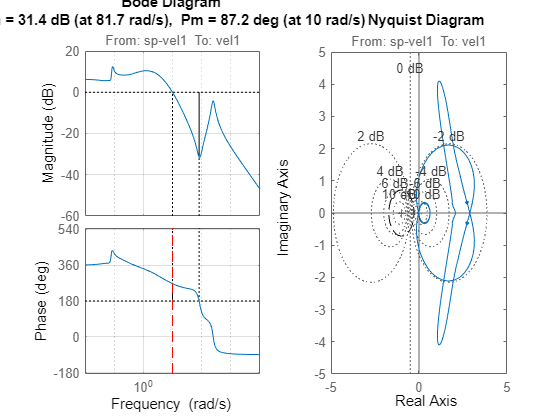

Kp=x(1); Ki=x(2); Kd=x(3); Tfd=x(4); Tfu=x(5);

Cv_joint1 = Kp+Kd*s/(Tfd*s+1);   % progettiamo un controllore nella forma della funzione di trasferimento
Cv_joint1.InputName = 'sp-vel1';
Cv_joint1.OutputName = 'torque';

Loop_int_joint1 = process*Cv_joint1;

figure
subplot(1,2,1)
margin(Loop_int_joint1)
hold on
plot(internal_joint1.wc_des*[1 1],ylim,'--r')
hold off

subplot(1,2,2)
% MS = max(S) = max(1/(1+L)) -> 1/Ms = min(1+L) = min(L-(-1))
nyquist(Loop_int_joint1)
axis equal
grid on 
hold on
angolo=linspace(-pi,pi);
plot(-1+1/internal_joint1.MS*sin(angolo),1/internal_joint1.MS*cos(angolo),'--k')
hold off
xlim([-5 5]); ylim([-5 5])

### PID esterno

Processo da controllare (da velocità - set point per il controllore interno - a posizione)

controller_int = tf2ss(Cv_joint1.Numerator{1},Cv_joint1.Denominator{1});
process = controller_int*modelC_joint1 * 1/(1+controller_int*modelC_joint1) * 1/s;

Necessario integratore perchè il modello in uscita fornisce la velocità, mentre noi vogliamo controllare la posizione.

**N.B.: il controllore esterno ****non**** vede **`Cv*P*1/s`**, ma **`Cv*P/(1+Cv*P)*1/s`** (in pratica vede tutto il sistema interno in closed-loop!**

#### Cifra di merito da minimizzare


$$J=\left( \omega_c - \omega_{c,des}\right)^2$$


- $\omega_c$: frequenza (pulsazione) di taglio

- $\omega_{c,des}$: valore desiderato

Le incognite del problema sono $x=[K_p, \; K_i, \; K_d, \; T_{fd}, \; T_{fu}]$ (alcune verranno forzate a 0, se non vogliamo utilizzarle).

external_joint2.wc_des = 2;
J = @(x)pid_filt_cost_function(x,process,external_joint2.wc_des);

#### Vincoli

- massima sensitività $MS<1.4$ per garantire la robustezza (1.4 molto robusto, 2 poco robusto ma aggressivo)

- La funzione di anello chiuso $F$ deve avere modulo limitato con $\omega\geq\omega_h$

- La funzione fra disturbo sul carico e l'uscita deve modulo limitato quando $\omega\leq\omega_l$

- Il margine di fase deve essere almeno 60°

Parametri da tarare

% Massima sensitività
external_joint2.MS = 2;

% Reiezione disturbo di misura
external_joint2.wh = 1000;
external_joint2.Fh_max = 0.1;

% Reiezione disturbo sul carico
external_joint2.wl = 12;
external_joint2.Dh_max = 0.1;

% Minimo margine di fase tollerabile
external_joint2.PM_min = 60;

Per calcolare in maniera corretta $MS$ passo alla funzione anche il vettore delle pulsazioni naturali che voglio testare

w_vector=logspace(log10(wpeso0),log10(wpeso1))';    % wpeso0 e wpeso1 vengono caricate all'atto del caricamento del modello stimato
w_vector=sort([w_vector;external_joint2.wl;external_joint2.wh]);

nlcon = @(x)pid_filt_constraints(x, process, w_vector, ...
                                 external_joint2.MS, external_joint2.wh, external_joint2.Fh_max, ...
                                 external_joint2.wl, external_joint2.Dh_max, external_joint2.PM_min);

#### Ottimizzazione

Parametri da tarare

% Punto iniziale
external_joint1.x0_Kp = 1;
external_joint1.x0_Ki = 1;
external_joint1.x0_Kd = 0.01;
external_joint1.x0_Tfd = 10;
external_joint1.x0_Tfu = 0;

% Limiti inferiori
external_joint1.lb_Kp = 0.01;
external_joint1.lb_Ki = 1;
external_joint1.lb_Kd = 0.01;
external_joint1.lb_Tfd = 0.01;
external_joint1.lb_Tfu = 0;

% Limiti superiori
external_joint1.ub_Kp = 100;
external_joint1.ub_Ki = 10;
external_joint1.ub_Kd = 100;
external_joint1.ub_Tfd = 100;
external_joint1.ub_Tfu = 0;

Lanciare ottimizzatore

gs = GlobalSearch('Display','iter');
x0 = [external_joint2.x0_Kp, external_joint2.x0_Ki, external_joint2.x0_Ki, external_joint2.x0_Tfd, external_joint2.x0_Tfu];

problem = createOptimProblem('fmincon','x0',x0, ...
                             'objective',J, ...
                             'lb',[external_joint2.lb_Kp, external_joint2.lb_Ki, external_joint2.lb_Kd, external_joint2.lb_Tfd, external_joint2.lb_Tfu], ...
                             'ub',[external_joint2.ub_Kp, external_joint2.ub_Ki, external_joint2.ub_Kd, external_joint2.ub_Tfd, external_joint2.ub_Tfu], ...
                             'nonlcon',nlcon);
x = run(gs,problem)

#### Controllore ottenuto

Kp=x(1); Ki=x(2); Kd=x(3); Tfd=x(4); Tfu=x(5);

Cp_joint1 = Kp+Ki/s+Kd*s/(Tfd*s+1);   % progettiamo un controllore nella forma della funzione di trasferimento
Cp_joint1.InputName = 'sp-pos1';
Cp_joint1.OutputName = 'vel';

Loop_ext_joint1 = process*Cp_joint1;

figure
subplot(1,2,1)
margin(Loop_ext_joint1)
hold on
plot(external_joint2.wc_des*[1 1],ylim,'--r')
hold off

subplot(1,2,2)
% MS = max(S) = max(1/(1+L)) -> 1/Ms = min(1+L) = min(L-(-1))
nyquist(Loop_ext_joint1)
axis equal
grid on 
hold on
angolo=linspace(-pi,pi);
plot(-1+1/external_joint2.MS*sin(angolo),1/external_joint2.MS*cos(angolo),'--k')
hold off
xlim([-5 5]); ylim([-5 5])

## Giunto 2

### PD interno

### PID esterno